# CS229 - Machine Learning

## Project

## Load Data

close all
clear
clc
warning('off','all')

% Load Data
Wind_Data = readtable('Wind_Data.xlsx');
EQ_Data = readtable('EQ_Data_Clean.csv');
SO2_Data = readtable('SO2_Data_Clean.csv');

B = 2700

### Sensor Locations

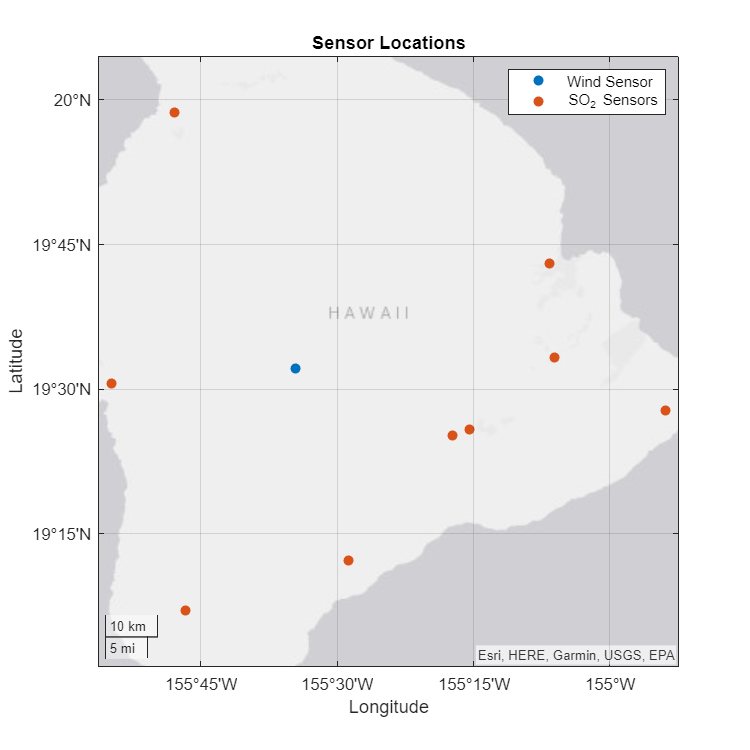

% Sensor Locations
fig = figure('Position', [0,0,600,600]);
geoscatter(19.5362,	-155.5763, 'filled');
hold on
geoscatter(SO2_Data.SITE_LATITUDE, SO2_Data.SITE_LONGITUDE, 'filled');
hold off
legend('Wind Sensor', 'SO_2 Sensors')
title('Sensor Locations')

### EQ Events

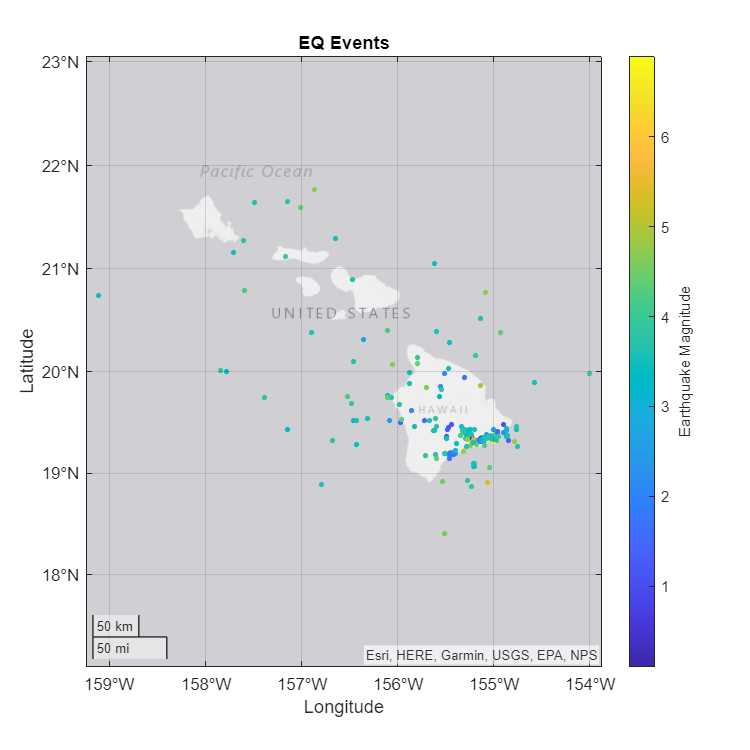

% Sensor Locations
fig = figure('Position', [0,0,600,600]);
s = geoscatter(EQ_Data.latitude, EQ_Data.longitude, 10, EQ_Data.mag, "filled");
c = colorbar();
c.Label.String = "Earthquake Magnitude";
title('EQ Events')

### Time Histories

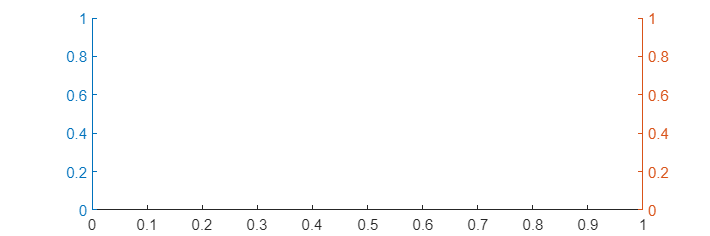

% SO2 Concentration vs EQ Magnitude - Time History
fig = figure('Position', [0,0,1200,400]);
yyaxis left

scatter(datetime(SO2_Data.Date,'ConvertFrom','datenum'), SO2_Data.DailyMax1_hourSO2Concentration, 10, 'filled')

Unable to resolve the name SO2_Data.Date.

ylabel('SO_2 Concentration [ppb]')
ylim([0, inf])
xlabel('Days')
yyaxis right
scatter(datetime(EQ_Data.Date,'ConvertFrom','datenum'), EQ_Data.mag, 10, 'filled')
ylabel('Moment Magnitude [M_w]')
xlabel('Years')
ylim([0, inf])
title('SO_2 Concentration vs EQ Magnitude - Time History')
% SO2 Concentration vs Relative Humidity - Time History
fig = figure('Position', [0,0,1200,400]);
yyaxis left
scatter(datetime(SO2_Data.Date,'ConvertFrom','datenum'), SO2_Data.DailyMax1_hourSO2Concentration, 10, 'filled')
ylabel('SO_2 Concentration [ppb]')
ylim([0, inf])
xlabel('Days')
yyaxis right
scatter(datetime(Wind_Data.Date,'ConvertFrom','datenum'), Wind_Data.RELATIVEHUMIDITY, 10, 'filled')
ylabel('Relative Humidity [RH]')
xlabel('Years')
ylim([0, inf])
title('SO_2 Concentration vs Relative Humidity - Time History')
% SO2 Concentration vs Temperature - Time History
fig = figure('Position', [0,0,1200,400]);
yyaxis left
scatter(datetime(SO2_Data.Date,'ConvertFrom','datenum'), SO2_Data.DailyMax1_hourSO2Concentration, 10, 'filled')
ylabel('SO_2 Concentration [ppb]')
ylim([0, inf])
xlabel('Days')
yyaxis right
scatter(datetime(Wind_Data.Date,'ConvertFrom','datenum'), Wind_Data.TEMPERATUREAT2METERS, 10, 'filled')
ylabel('Temperature [°C]')
xlabel('Years')
ylim([0, inf])
title('SO_2 Concentration vs Temperature - Time History')
% SO2 Concentration vs Wind Speed - Time History
fig = figure('Position', [0,0,1200,400]);
yyaxis left
scatter(datetime(SO2_Data.Date,'ConvertFrom','datenum'), SO2_Data.DailyMax1_hourSO2Concentration, 10, 'filled')
ylabel('SO_2 Concentration [ppb]')
ylim([0, inf])
xlabel('Days')
yyaxis right
scatter(datetime(Wind_Data.Date,'ConvertFrom','datenum'), Wind_Data.WINDSPEED, 10, 'filled')
ylabel('Wind Speed [m/s]')
xlabel('Years')
ylim([0, inf])
title('SO_2 Concentration vs Wind Speed - Time History')

### Variable Correlations

% % Sensor Locations
% All_Data = readtable("All_Data.csv");
% All_Data = removevars(All_Data,["Month", "Cluster_ID", "Risk_Label"]);
% R = corrplot(All_Data);